# The SIR-X Model

- **use parameter names that correspond to the other models**

#### **The Model**

The SIR-X model was created based off the recent Corona virus epidemic. It takes into account the different measures taken by populations (via the government) to reduced the transmission rate. Firstly, the individuals of the populations follow a containment measure where, i.e. reduced contact between individuals. This, therefore would put a a number of the suseptible population in the same situation as that of the removed category. Since, they would not 'take part' in the transmission if they aren't exposed to it. Another factor to take into account is the quarantining of infected individuals. The quarantining process would also remove the infected individuals from being involved with the transmission. Infecteds in quaratining would have little to no chance of infecting other suseptibles. 

Taking into account these measures we can modifiy the traditional SIR so that it includes new parameters that invovles the contained and quaratined individuals. 

The aforementioned modified SIR model is presented in the following ODEs : 


$$\frac{\textrm{dS}}{\textrm{dt}}=-\alpha \textrm{SI}-\kappa_0 S$$



$$\frac{\textrm{dI}}{\textrm{dt}}=$$

$$\alpha \textrm{SI}-\beta I-\kappa_0 I-\kappa I$$



$$\frac{\textrm{dR}}{\textrm{dt}}=\beta I+\kappa_0 S$$



$$\frac{\textrm{dX}}{\textrm{dt}}=\left(\kappa_0 +\kappa \right)I$$


The $\alpha$ and $\beta$ represents the transmission and recovery  rates of the traitional SIR model. $\kappa_0$ is a new parameter that represents the containment rate and would be applicable to both the S and I groups. $\kappa$ is the other new parameter representing the quaratine rate of the already infective population. Hence it is only applicable to the I group.

X is the new compartment added to this model and it quantifies the individuals who are symptomatic infecteds that are quarantined.

The following is the block diagram for this model. 

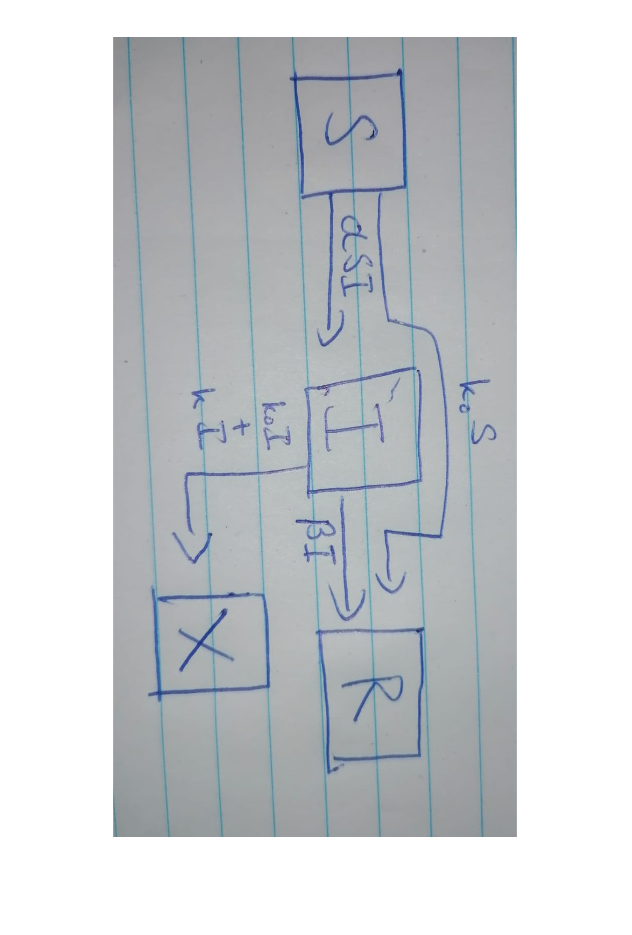

imshow("SIRX_Block_diagram.jpeg")

## Solution with Euler method

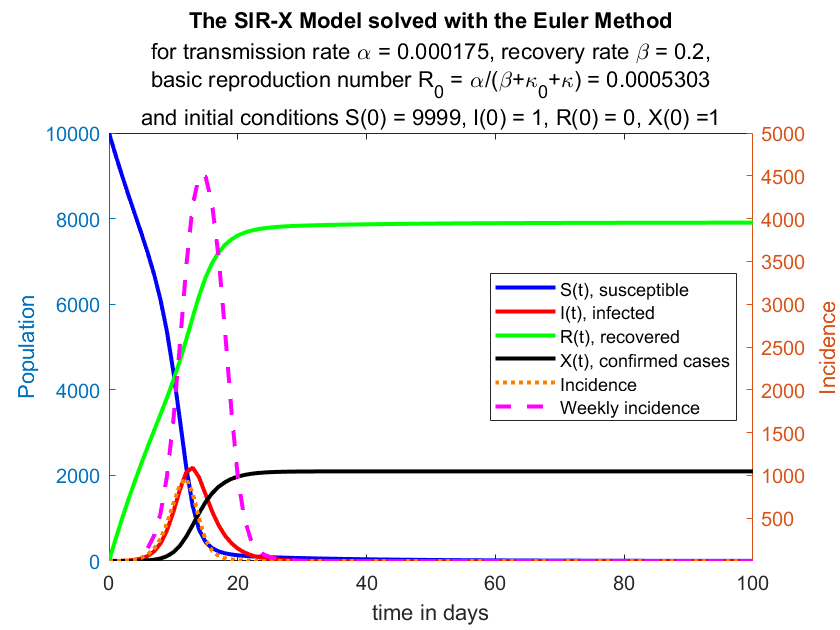

figure;

%%% The initial values

tmax = 100;

S = zeros(1, tmax + 1);
I = zeros(1, tmax + 1);
R = zeros(1, tmax + 1);
X = zeros(1, tmax + 1);
S(1) = 9999;
I(1) = 1;
R(1) = 0;
X(1)= 1;
N=S(1)+I(1)+R(1);

Incidence = zeros(1, tmax + 1);
Incidence(1) = 0;

Weekly_Incidence = zeros(1, tmax - 6);

%%% The parameters

p=0.35;  % infection probability 
c=5;    % contact rate
ko = 0.05; % containment rate
k= 0.08; % quaratine rate

alpha = p*c/N;
beta = 0.2;

R_eff=alpha/(beta+ko+k);


%%% The Euler method

T = zeros(1,tmax + 1);
T(1) = 0;

for t = 1:tmax
        
    T(t+1) = t;
        
    S(t+1) = S(t) - alpha*I(t)*S(t) - ko*S(t) ;   
    I(t+1) = I(t) + (alpha*I(t)*S(t)) - beta*I(t) - k*I(t) -ko*I(t) ; 
    R(t+1) = R(t) + beta*I(t) + ko*S(t);
    X(t+1)= X(t) + (ko+k)*I(t);
    
    Incidence(t+1) = alpha*I(t)*S(t);
    
        if t > 5
                
            Weekly_Incidence(t-5) = sum(Incidence(t-5:t+1));
            
        end
end


%%%% The plot

yyaxis left
plot(T, S, 'b','LineWidth',2,'LineStyle',"-"); hold on;
plot(T, I, 'r','LineWidth',2,'LineStyle',"-");
plot(T, R, 'g','LineWidth',2,'LineStyle',"-");
plot(T, X, 'k','LineWidth',2,'LineStyle',"-");
ylabel('Population');

yyaxis right 
plot(T, Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(T(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylim([1 5000]);
ylabel('Incidence');

title('The SIR-X Model solved with the Euler Method')
subtitle({['for transmission rate \alpha = ',num2str(alpha),', recovery rate \beta = ',num2str(beta),','], ...
    ['basic reproduction number R_0 = \alpha/(\beta+\kappa_0+\kappa) = ',num2str(R_eff)], ...
    ['and initial conditions S(0) = ',num2str(S(1)),', I(0) = ',num2str(I(1)),', R(0) = ',num2str(R(1)),', X(0) =',num2str(X(1))]})
legend('S(t), susceptible', 'I(t), infected', 'R(t), recovered','X(t), confirmed cases','Incidence', 'Weekly incidence', 'Location', 'east')

xlabel('time in days');
xlim([0 100]);

hold off;

## Solution with ode45

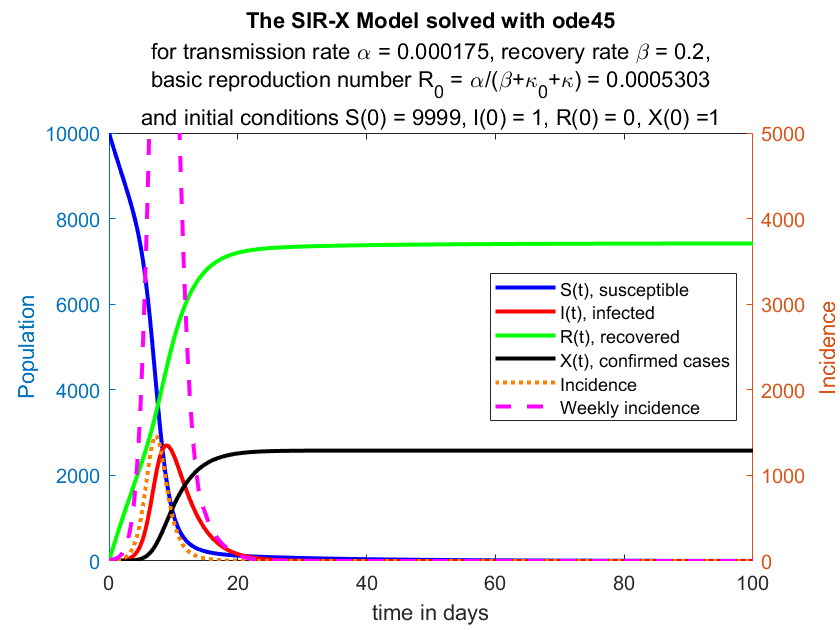

figure;

%%%% The parameters and the initial values

tRange = [0 100];
beta = 0.2;
alpha = 0.000175;
ko = 0.05;
k=0.08;

R_eff=alpha/(beta+ko+k);
Y0 = [9999; 1; 0; 1];

[tSol,YSol] = ode45(@SIRXmodel,tRange,Y0);

%%%% The plot

S = YSol(:,1);
I = YSol(:,2);
R = YSol(:,3);
X = YSol(:,4);

Incidence = alpha*S.*I;

sz = size(tSol);
Weekly_Incidence = zeros(sz(1)-6,sz(2));

for n = 7:sz(1)

    Weekly_Incidence(n-6) = sum(Incidence(n-6:n));
 
end

yyaxis left
plot(tSol,S,'b','LineWidth',2,'LineStyle',"-"); hold on;
plot(tSol,I,'r','LineWidth',2,'LineStyle',"-");
plot(tSol,R,'g','LineWidth',2,'LineStyle',"-");
plot (tSol,X,'k','LineWidth',2,'LineStyle',"-")
ylabel('Population');

yyaxis right
plot(tSol,Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(tSol(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylabel('Incidence');
ylim([0 5000]);

legend('S(t), susceptible', 'I(t), infected', 'R(t), recovered','X(t), confirmed cases','Incidence', 'Weekly incidence', 'Location', 'east');
title('The SIR-X Model solved with ode45');
subtitle({['for transmission rate \alpha = ',num2str(alpha),', recovery rate \beta = ',num2str(beta),','], ...
    ['basic reproduction number R_0 = \alpha/(\beta+\kappa_0+\kappa) = ',num2str(R_eff)], ...
    ['and initial conditions S(0) = ',num2str(Y0(1)),', I(0) = ',num2str(Y0(2)),', R(0) = ',num2str(Y0(3)), ', X(0) =', num2str(Y0(2))]})

xlabel('time in days');
xlim([0 100]);

hold off;

function dYdt = SIRXmodel(t,Y)  % TODO - Write the function declaration. Name the function SIRmodel

    % Extract S, I, and R from input vector Y
    S = Y(1); % susceptible
    I = Y(2); % infected
    R = Y(3); % recovered
    X = Y(4); %confirmed cases
    % Define the constants alpha and beta
    alpha = 0.000175;
    beta = 0.2;
    ko = 0.05;
    k=0.08;
    % Define dSdt, dIdt, dRdt,dXdt from the ODEs
    dSdt = -alpha*S*I - ko*S;
    dIdt = alpha*S*I - beta*I -ko*I -k*I ;
    dRdt = beta*I + ko*S;
    dXdt = (ko+k)*I;
    
    % Create output column vector dYdt
    dYdt = [dSdt; dIdt; dRdt;dXdt];
    
end